## Load Fall.mat from suite2p

%% read Fall file from suite2p  (update if necessary)
%make list of cells making assemblies

% PathSave='/Users/platel/Desktop/exp/analysis/';
% 
%  daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
%  namefull=[PathSave daytime 'ani175_plane1/'];
%  mkdir (namefull)    % make folder for saving analysis
load('/Users/platel/Desktop/exp/aurelie/444175_new/Fall.mat')

## Choose which type of assembly to process

assembly=assemblyortho;
%assembly=assemblystat;
%assembly=assemblyraw;
nbassemblies=length(assembly);

calcium=imread([path,'calcium.tif']);

## Load calcium mask from suite2p (from Fall.mat)

m=0;
NCell=sum(iscell(:,1)>0);

for n=1 : length(stat)

    if iscell(n,1)==1
        m=m+1;

        outline_gcampx(m)={stat{1, n}.xext+1};
        outline_gcampy(m)={stat{1, n}.yext+1};

        neuropil(m)={stat{1, n}.neuropil_mask};

        Coomasqx(m)={stat{1, n}.xpix+1};%+1  to adpat suite2p output   ONLY 1 ??????
        Coomasqy(m)={stat{1, n}.ypix+1};

    end

end

## generation of poly2mask (binary mask) for using regionprops and measure area and centroid

%making  calcium mask (binary) for comparison
[width ,height]=size (blue);
tic 
gcamp_mask=uint16(zeros(NCell,width,height));
gcamp_props = struct('Area', [], 'Centroid', []);
parfor n=1:NCell
    gcamp_mask(n,:,:) = poly2mask(double(cell2mat(outline_gcampx(n))), double(cell2mat(outline_gcampy(n))), width, height);
    gcamp_props(n) = regionprops(gcamp_mask(n,:,:), 'area' ,'Centroid');
end


## calculation distance centroid with gcamp only


%distance between all gcamp centroid 
size_pixel=705/512;
% tmp=[gcamp_props.Centroid];
tmp=[];
for n=1:NCell
    tmp(n,:,:,:)=gcamp_props(n).Centroid;
end

distances_gcamp = pdist(tmp); % Calcul des distances entre toutes les paires de centres
Z = squareform(distances_gcamp);
meandistance_gcamp = mean(distances_gcamp)*size_pixel;

%distance between cells in assembly

for num=1:nbassemblies
    cellassembly(num)=length(cell2mat(assembly(num)));
    tmp=[];
    i=0;
    for m=cell2mat(assembly(num))
        i=i+1;
        tmp(i,:,:,:)=gcamp_props(m).Centroid;
    end
    distances = pdist(tmp); % Calcul des distances entre toutes les paires de centres
    meandistance_assembly(num) = mean(distances)*size_pixel;    
end
mean_mean_distance_assembly=mean(meandistance_assembly);


%shuffle
nbsurrogate=1000;
tic
for num=1:nbassemblies
    for sur=1 : nbsurrogate
    
        numcell=length(cell2mat(assembly(num)));
        x = randi([1,NCell],1,numcell);
        distances = pdist(centroid_gcamp(x,:)); % Calcul des distances entre toutes les paires de centres
        temp(sur) = mean(distances)*size_pixel;  

    end
    meandistance_assemblysh(num)=mean(temp);
end
toc
mean_distance_assemblysh_TH=prctile(meandistance_assemblysh,95);
victory=0
for num=1:nbassemblies
    if meandistance_assembly(num)>prctile(meandistance_assemblysh(num),95)
        victory=victory+1
    end
end

% distance between cells all colored cells(own masks)
%red
distances = pdist(centroid_red); % Calcul des distances entre toutes les paires de centres
meandistance_red = mean(distances)*size_pixel;    
%green
distances = pdist(centroid_green); % Calcul des distances entre toutes les paires de centres
meandistance_green = mean(distances)*size_pixel;  
%blue
distances = pdist(centroid_red); % Calcul des distances entre toutes les paires de centres
meandistance_blue = mean(distances)*size_pixel;  


## plot assemblies 

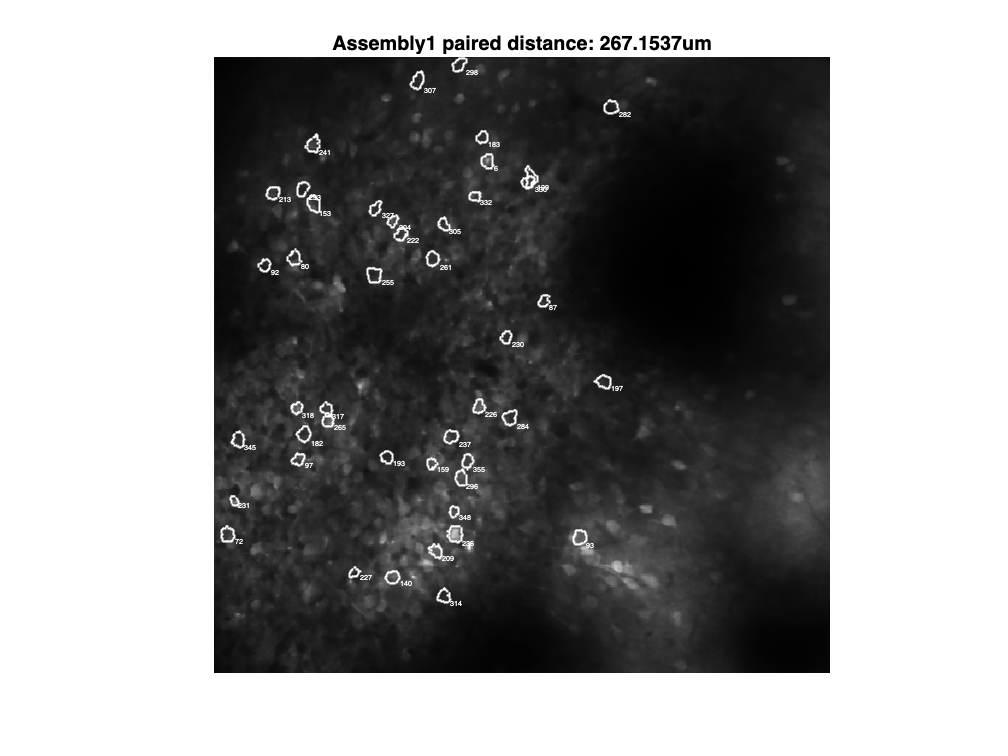

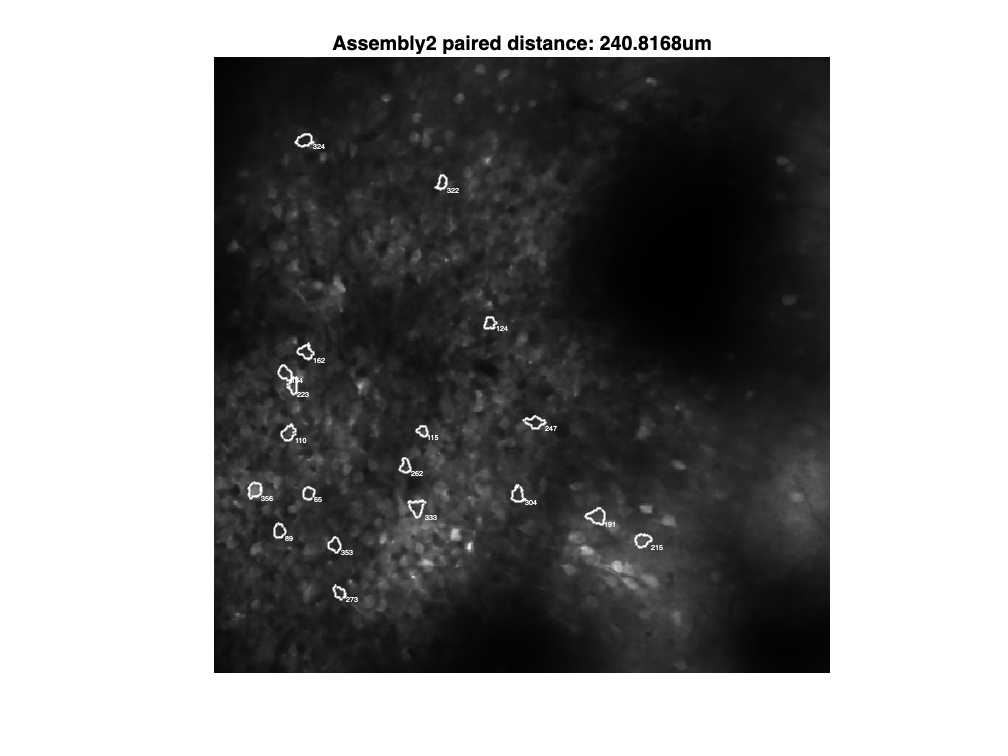

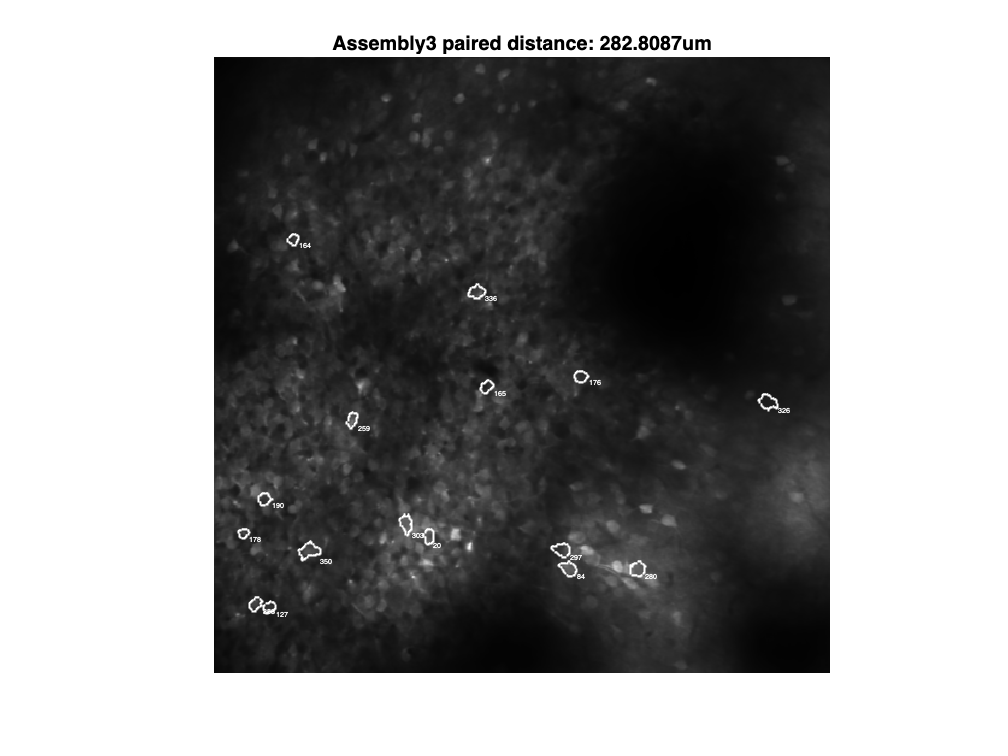

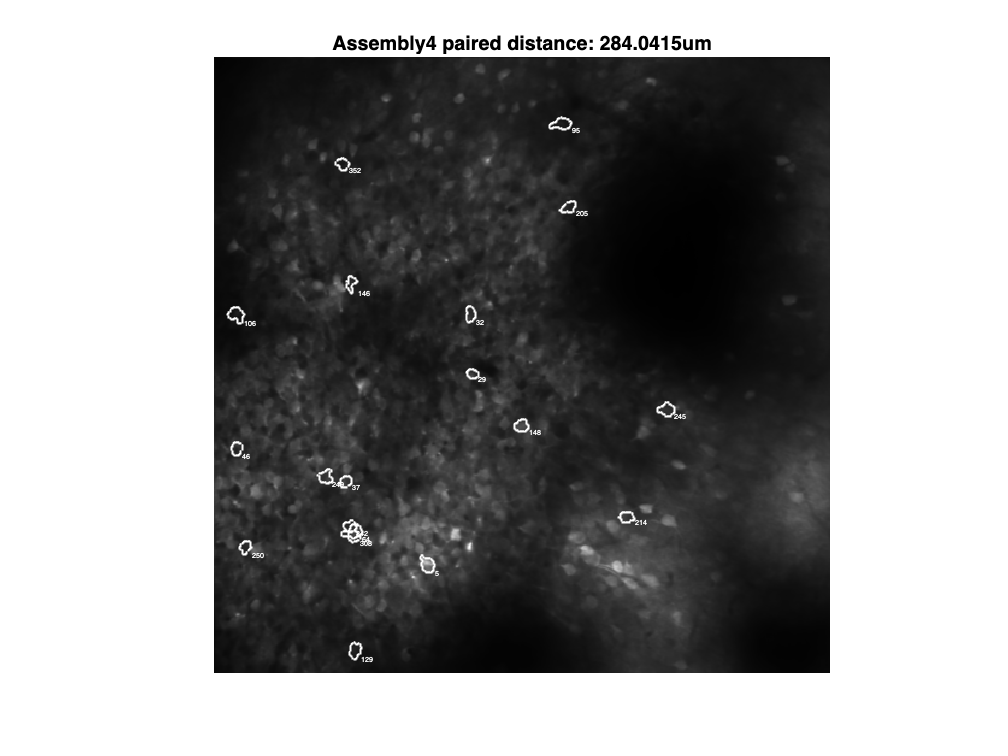

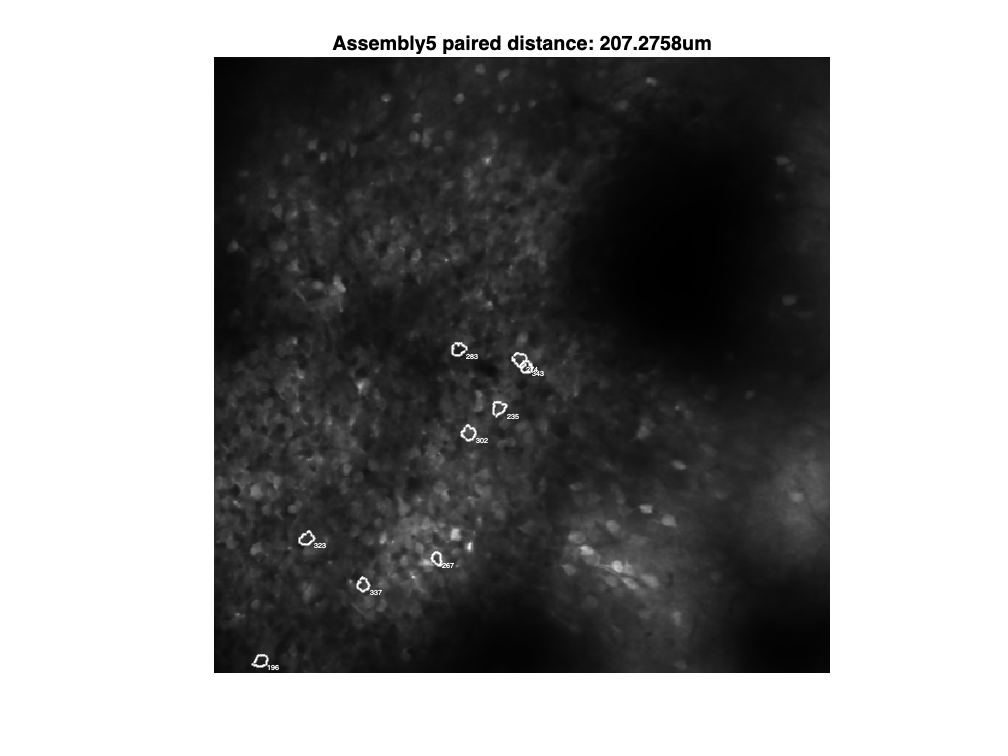

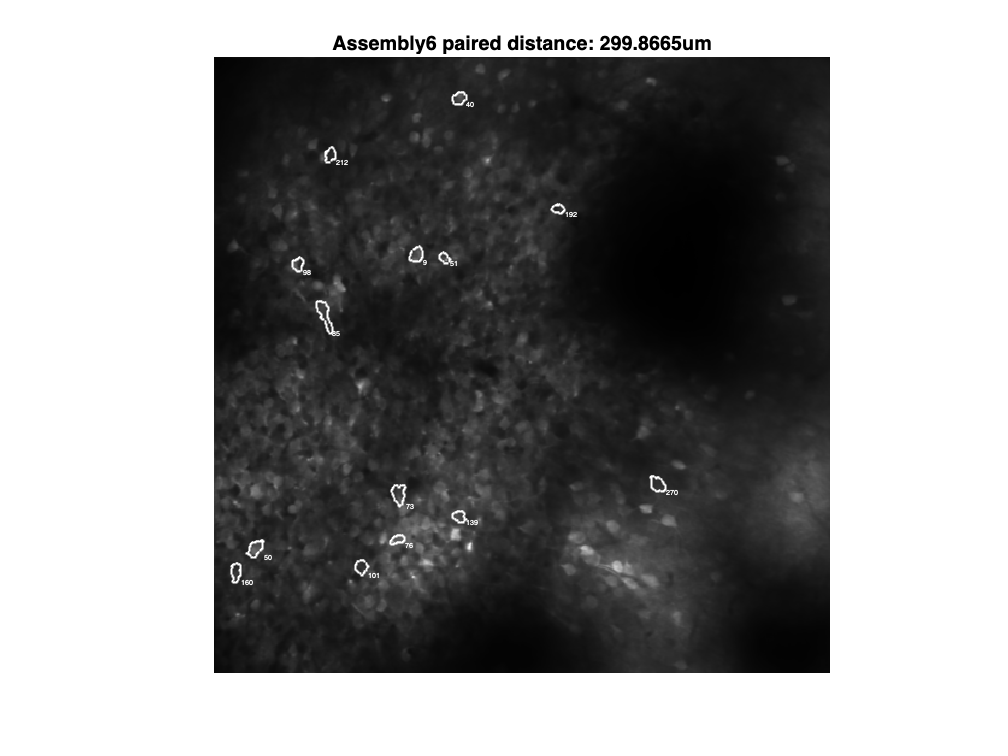

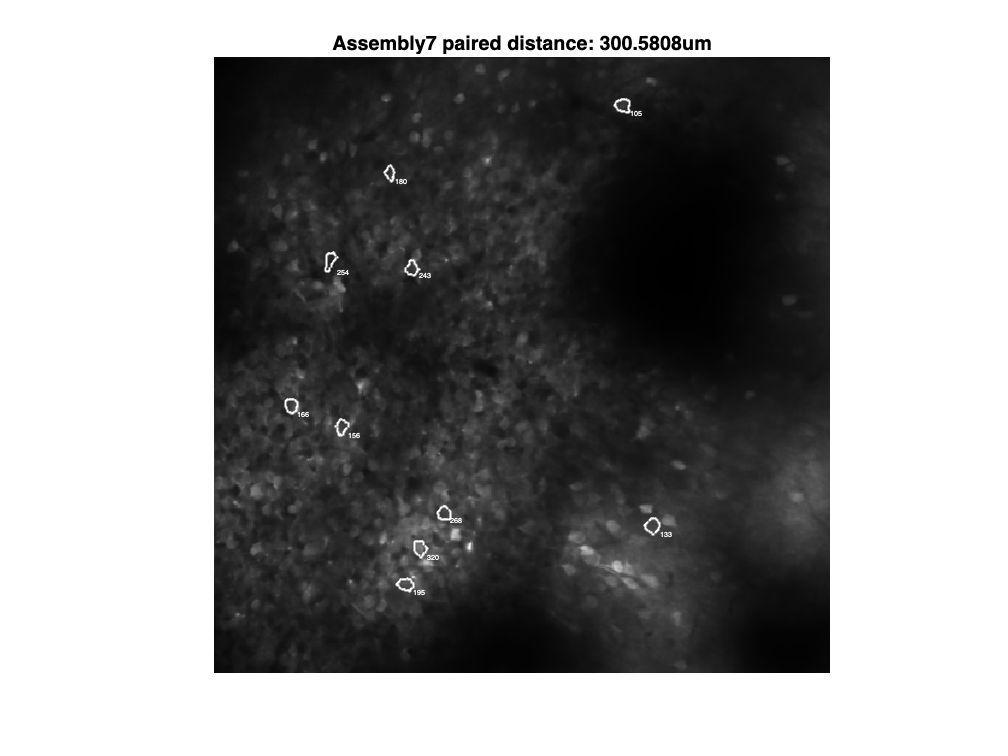

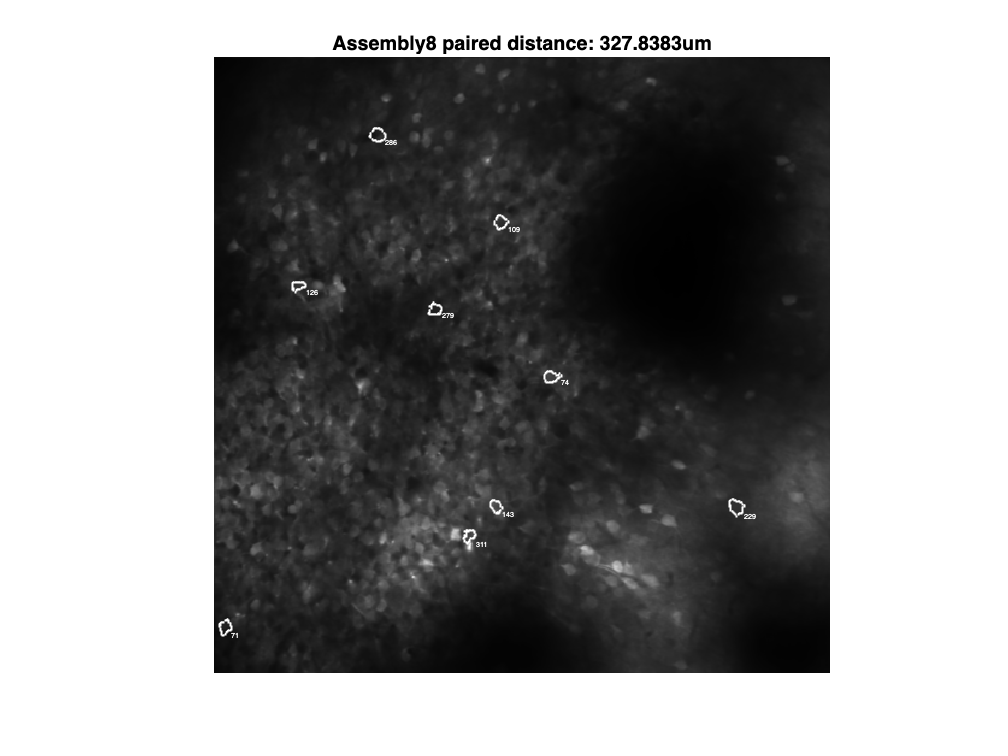

for num=1:nbassemblies
    figure
    imagesc(calcium)
    colormap ("gray")
    
    title(['Assembly' num2str(num) ' paired distance: ' num2str(meandistance_assembly(num)) 'um'])
    hold on

    for n=cell2mat(assembly(num))

            x=cell2mat(outline_gcampx(n));
            y=cell2mat(outline_gcampy(n));
            text(max(x),max(y),num2str(n),"FontSize",4,"Color",'w')
            plot(x, y, '.', 'MarkerSize', 4,"Color",'w');
            axis off
            axis image

    end
    name=['Assembly' num2str(num)];
    exportgraphics(gcf,name,'Resolution',300);
end